姓名：莊璧如 學號：111321534

ex1

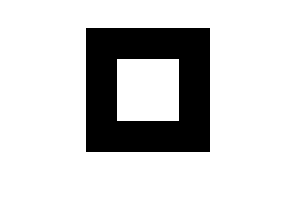

A=zeros(128,128);
A(33:96,33:96)=255*ones(64,64);
imshow(A,[])

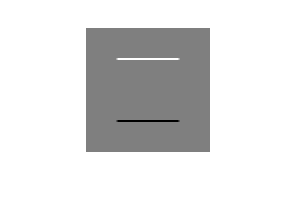


t=[-1 -1 -1;0 0 0;1 1 1];
ay=filter2(t,A,'same');
imshow(ay,[])

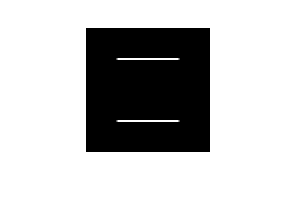

imshow(abs(ay),[])

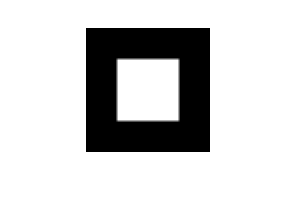


a=ones(3,3)/9;
a2=filter2(a,A,'same');
imshow(a2,[])

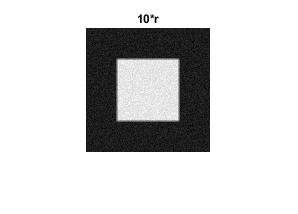


r=randn(size(a2));
imshow(a2+10*r,[])
title('10*r')

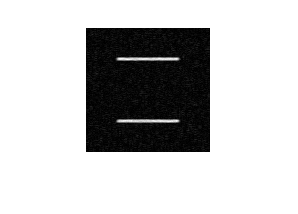

a3=filter2(t,a2+10*r,'same');
imshow(abs(a3),[])
title(a3)

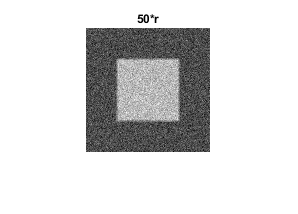

imshow(a2+50*r,[])
title('50*r')

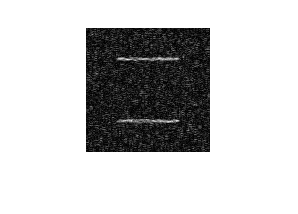

a4=filter2(t,a2+50*r,'same');
imshow(abs(a4),[])
title(a4)

ex2

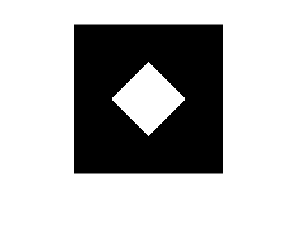

A=zeros(128,128);
A(33:96,33:96)=255*ones(64,64);
B= imrotate(A, 45);
imshow(B,[])

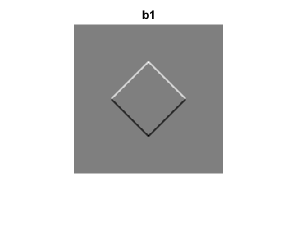

t=[-1 -1 -1;0 0 0;1 1 1];
b1=filter2(t,B,'same');
imshow(b1,[])
title('b1')

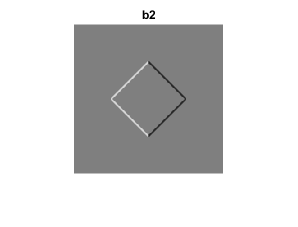

t2=[-1 0 1;-1 0 1;-1 0 1];
b2=filter2(t2,B,'same');
imshow(b2,[]);
title('b2')

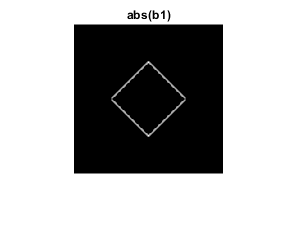

imshow(abs(b1),[])
title('abs(b1)')

ex3

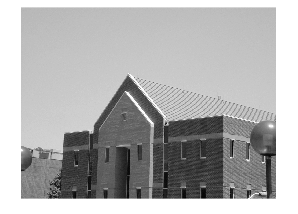

house=imread('house.jpg');
imshow(house,[])

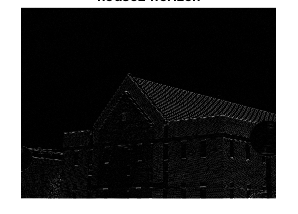

t3=[-1 -2 -1;0 0 0;1 2 1];
house2=filter2(t3,house,'same');
imshow(abs(house2),[]);
title('house2-horizon')

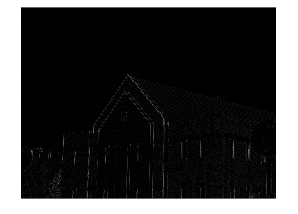

t4=[-1 0 1;-2 0 2;-1 0 1];
house3=filter2(t4,house,'same');
imshow(abs(house3),[])

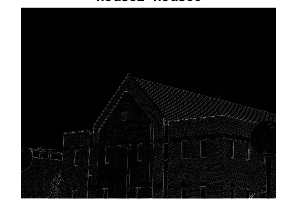

imshow(abs(house2+house3),[])
title('house2+house3')

ex4

A=zeros(128,128);
A(33:96,33:96)=255*ones(64,64);
imshow(A);

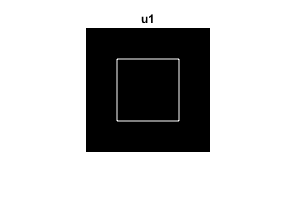

t5=[0 -1 0;-1 4 -1;0 -1 0];
u1=filter2(t5,A,'same');
imshow(abs(u1),[]);
title('u1')

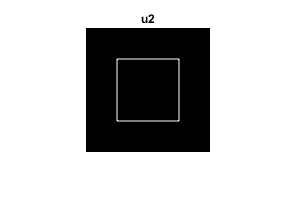

t6=[-1 -1 -1;-1 8 -1;-1 -1 -1];
u2=filter2(t5,A,'same');
imshow(abs(u2),[]);
title('u2')

ex5

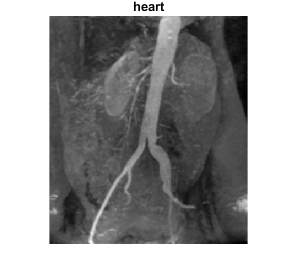

heart=imread('heart (1).jpg');
imshow(heart,[])
title('heart')

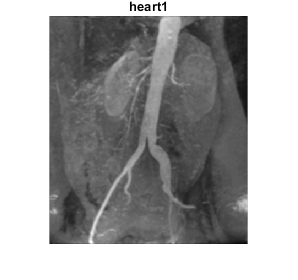

g=fspecial('gaussian');
heart1=filter2(g,heart,'same');
imshow(heart1,[])
title('heart1')

t7=[-1 -1 -1;-1 8 -1;-1 -1 -1];
heart2=filter2(t7,heart,'valid')

heart2 =      4     6     3     3     5     1     2     5    -2     2    -1     4    -8     4     5     1   -12    -1     7    -7    -7     0     0     2     6     2    -2     4    -5     4    -1    -2    -2     0   -11    -5    -3     6     1     7     3    -4     2    -1     2    -2    -7    -5    -7    -4
    -6    -3     4     7    -3     1    -3    15    16     6    -1    -2    -4    -3    -1    -7    -7    -5    -3     0     2     4    -2     2     5     0    -6     8     6     3     7     1    -2    -7    -2    -8     3     4     1     0    -3     0    -8    -9   -14    -5    -2     9    -8   -20
    -3   -13    -9     1    -2    -1     1    17    10     9    -5    -9    -4    -7     1   -19    -5     3     3    -5    -2     4    -5    -5     1     4     7     8     4     5     9     5    -4    -1    -6    -5     0     3     3    11    -4    -4    -9     3     1    -2     0     1     2    -3
    -8   -11    -5    -9    -8     3     7     6     9    -5     2   -11    -4    -5    

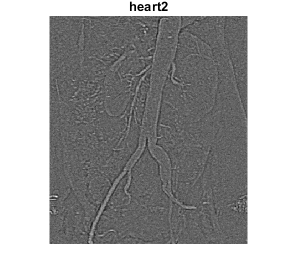

imshow(heart2,[])
title('heart2');

ex6

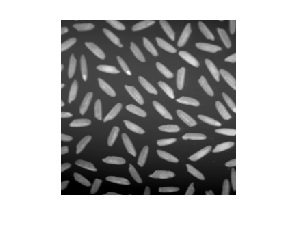

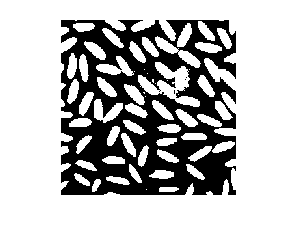

rice=imread('rice.tif');
imshow(rice,[])
figure, imshow(b>100)

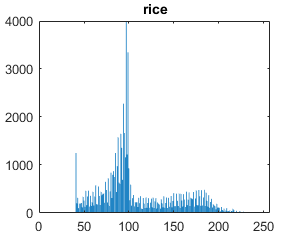

ret=myhist(rice);
bar(ret);
title('rice')

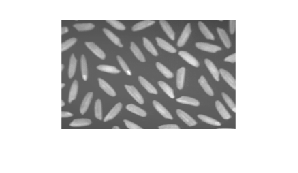

iu=rice(1:160,:);
imshow(iu)

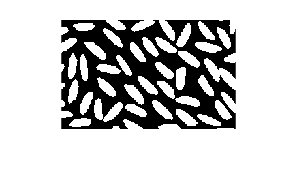

iut=iu>110;
imshow(iut)

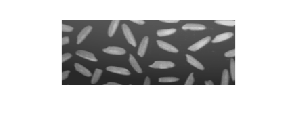

id=rice(161:256,:);
imshow(id)

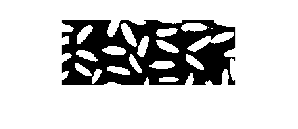

idt=id>90;
imshow(idt)

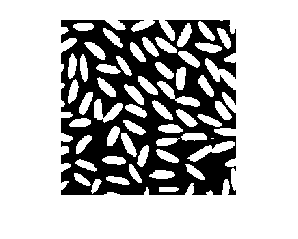

it=[iut;idt];
imshow(it)

function ret=myhist(I)
    ret = zeros(256,1); % initialize histogram vector
    [row, col]=size(I);
    for i=1:row
   
        for j=1:col
            ret(I(i,j)+1)=ret(I(i,j)+1)+1;
        end
    end
end